# Puma manipulator performing a biopsy. First approach

## Initiate the workspace

clc;
clear;
close all;
r=0.03; % Tumor radius
INI = transl(0.75, -0.15,0); % Pose of tumor center

## Plot a sketch of the environment of the robot

mdl_puma560
figure
hold on
axis ([-0.8 1.2 -0.8 0.8 -0.6 1.2])
p560.tool=transl(0,0,0.15)% RTB

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0.15), RPY/xyz = (0, 0, 0) deg               
 


p560.plot(qr,'zoom',2,'trail', {'r', 'LineWidth', 1.5});% RTB
xyz_tumor=transl(INI)

xyz_tumor =     0.7500
   -0.1500
         0


Tumor visualitation: Plot a 30 mm sphere centered at INI

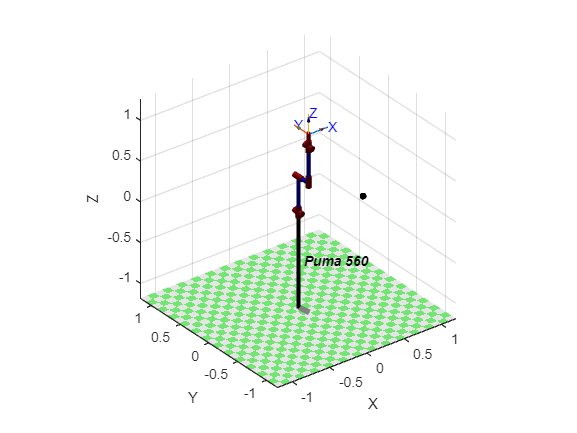

[X,Y,Z] = sphere;
r=0.03; % 30 mm
surf(X*r+xyz_tumor(1),Y*r+xyz_tumor(2),Z*r+xyz_tumor(3),'FaceColor',[1 0 0])
axis equal

## Task profile

Definition of approach pose 

T1=INI*transl(-0.3,0,0)*troty(pi/2)

T1 =          0         0    1.0000    0.4500
         0    1.0000         0   -0.1500
   -1.0000         0         0         0
         0         0         0    1.0000


T2=INI*troty(pi/2)

T2 =          0         0    1.0000    0.7500
         0    1.0000         0   -0.1500
   -1.0000         0         0         0
         0         0         0    1.0000


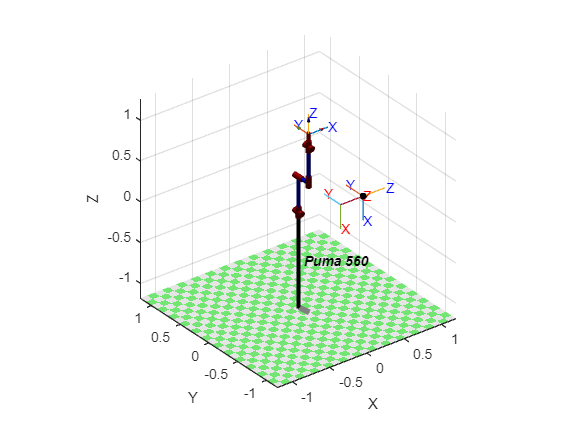

trplot (T1,'length',0.3,'arrow','width',0.2,'color','r')
trplot (T2,'length',0.3,'arrow','width',0.2,'color', 'b')

## Trajectories

Get Pose knowing joints angles

T0=p560.fkine(qr)

 

T0 = 
         1         0         0    0.0203
         0         1         0     -0.15
         0         0         1     1.014
         0         0         0         1


Get Joints angles knowing Pose

Check that q_0 = qr; There is other solution: see 'help' inike6s; example 'lun'

q_0 = p560.ikine6s(T0,'run'); 
q_1 = p560.ikine6s(T1,'run');
t_0=linspace(0,3,30)% trajectory time

t_0 =          0    0.1034    0.2069    0.3103    0.4138    0.5172    0.6207    0.7241    0.8276    0.9310    1.0345    1.1379    1.2414    1.3448    1.4483    1.5517    1.6552    1.7586    1.8621    1.9655    2.0690    2.1724    2.2759    2.3793    2.4828    2.5862    2.6897    2.7931    2.8966    3.0000


Joins space of the trajectory

Q_0=jtraj(q_0,q_1,t_0)

Q_0 =     0.0000    1.5708   -1.5708         0    0.0000   -0.0000
    0.0000    1.5707   -1.5693    0.0000    0.0005   -0.0000
    0.0000    1.5698   -1.5593    0.0000    0.0034   -0.0000
    0.0000    1.5675   -1.5341    0.0000    0.0110   -0.0000
    0.0000    1.5633   -1.4885    0.0000    0.0247   -0.0000
    0.0000    1.5571   -1.4191    0.0000    0.0454   -0.0000
    0.0000    1.5484   -1.3239    0.0000    0.0740   -0.0000
    0.0000    1.5374   -1.2019    0.0000    0.1105   -0.0000
    0.0000    1.5240   -1.0538    0.0000    0.1549   -0.0000
    0.0000    1.5083   -0.8808    0.0000    0.2067   -0.0000


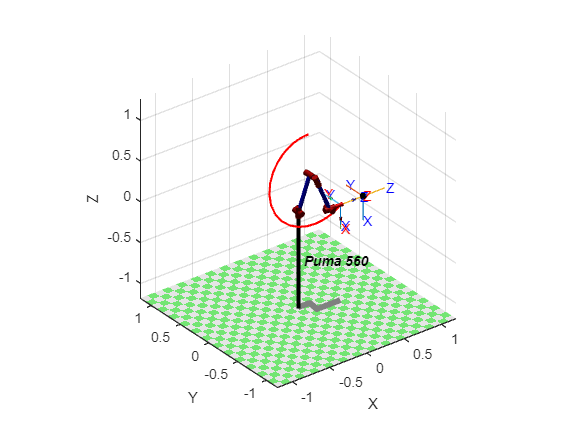

p560.plot(Q_0)

t_1=linspace(0,5,50)

t_1 =          0    0.1020    0.2041    0.3061    0.4082    0.5102    0.6122    0.7143    0.8163    0.9184    1.0204    1.1224    1.2245    1.3265    1.4286    1.5306    1.6327    1.7347    1.8367    1.9388    2.0408    2.1429    2.2449    2.3469    2.4490    2.5510    2.6531    2.7551    2.8571    2.9592    3.0612    3.1633    3.2653    3.3673    3.4694    3.5714    3.6735    3.7755    3.8776    3.9796    4.0816    4.1837    4.2857    4.3878    4.4898    4.5918    4.6939    4.7959    4.8980    5.0000


S=tpoly(0,1,t_1)

S =          0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


T_1_2 = ctraj(T1,T2,S);
Q_1 = p560.ikine6s(T_1_2);
QT=[Q_0;Q_1]

QT =     0.0000    1.5708   -1.5708         0    0.0000   -0.0000
    0.0000    1.5707   -1.5693    0.0000    0.0005   -0.0000
    0.0000    1.5698   -1.5593    0.0000    0.0034   -0.0000
    0.0000    1.5675   -1.5341    0.0000    0.0110   -0.0000
    0.0000    1.5633   -1.4885    0.0000    0.0247   -0.0000
    0.0000    1.5571   -1.4191    0.0000    0.0454   -0.0000
    0.0000    1.5484   -1.3239    0.0000    0.0740   -0.0000
    0.0000    1.5374   -1.2019    0.0000    0.1105   -0.0000
    0.0000    1.5240   -1.0538    0.0000    0.1549   -0.0000
    0.0000    1.5083   -0.8808    0.0000    0.2067   -0.0000


## Ploting the result

Experience with 'Zoom', 'View' and 'Worspace' to capture the best perpective.

p560.plot(QT,'zoom',2,'trail', {'r', 'LineWidth', 1.5});% RTB

## Recording a Video

The RTB will create a video for us.

Setting the enviroment again

%p560.plot( QT,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1],...
%             'trail','-','jaxes','zoom',2,'movie','Puma_doing_task.mp4')